% Clear workspace and figures
clear;
close all;

% Define the name
name = 'Sujeet';

% Calculate k using ASCII values
% k = mean(double(name)); % This gives 108.67
k=99

k = 99

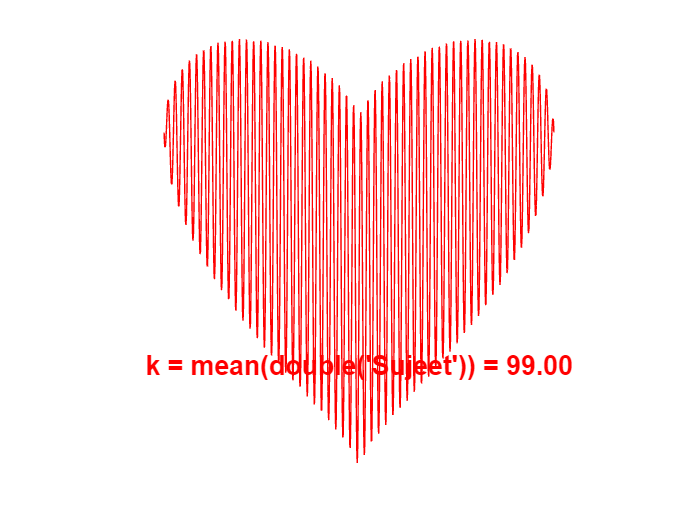




% Create x values within valid range
x = linspace(-sqrt(3), sqrt(3), 1000);

% Compute y values using the modified heart equation
y = abs(x).^(2/3) + 0.9 * sin(k * x) .* sqrt(3 - x.^2);

% Create figure with white background
figure('Color', 'white');

% Plot the heart in blue
plot(x, y, 'r-', 'LineWidth', 0.5);

% Improve axis aesthetics
axis equal;
axis off;

% Set figure size and position
set(gcf, 'Position', [100, 100, 800, 600]);

% Add simple red text below
text(0, -0.5, ...
    ['k = mean(double(''', name, ''')) = ', num2str(k, '%.2f')], ...
    'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'top', ...
    'FontSize', 16, ...
    'Color', 'r', ...
    'FontWeight', 'bold');

% Save high-quality image
exportgraphics(gcf, 'clean_final.png', 'Resolution',300);